load ryan3_gen_data.mat


#### 학습 / 검증 / 테스트 데이타 셋 선정. 배치별로 하면 데이타가 균일하지 않는다. 따라서 균일한 데이타를 얻도록 수정

전체 데이타 셋의 discahrge Q 를 smooth해서 표시

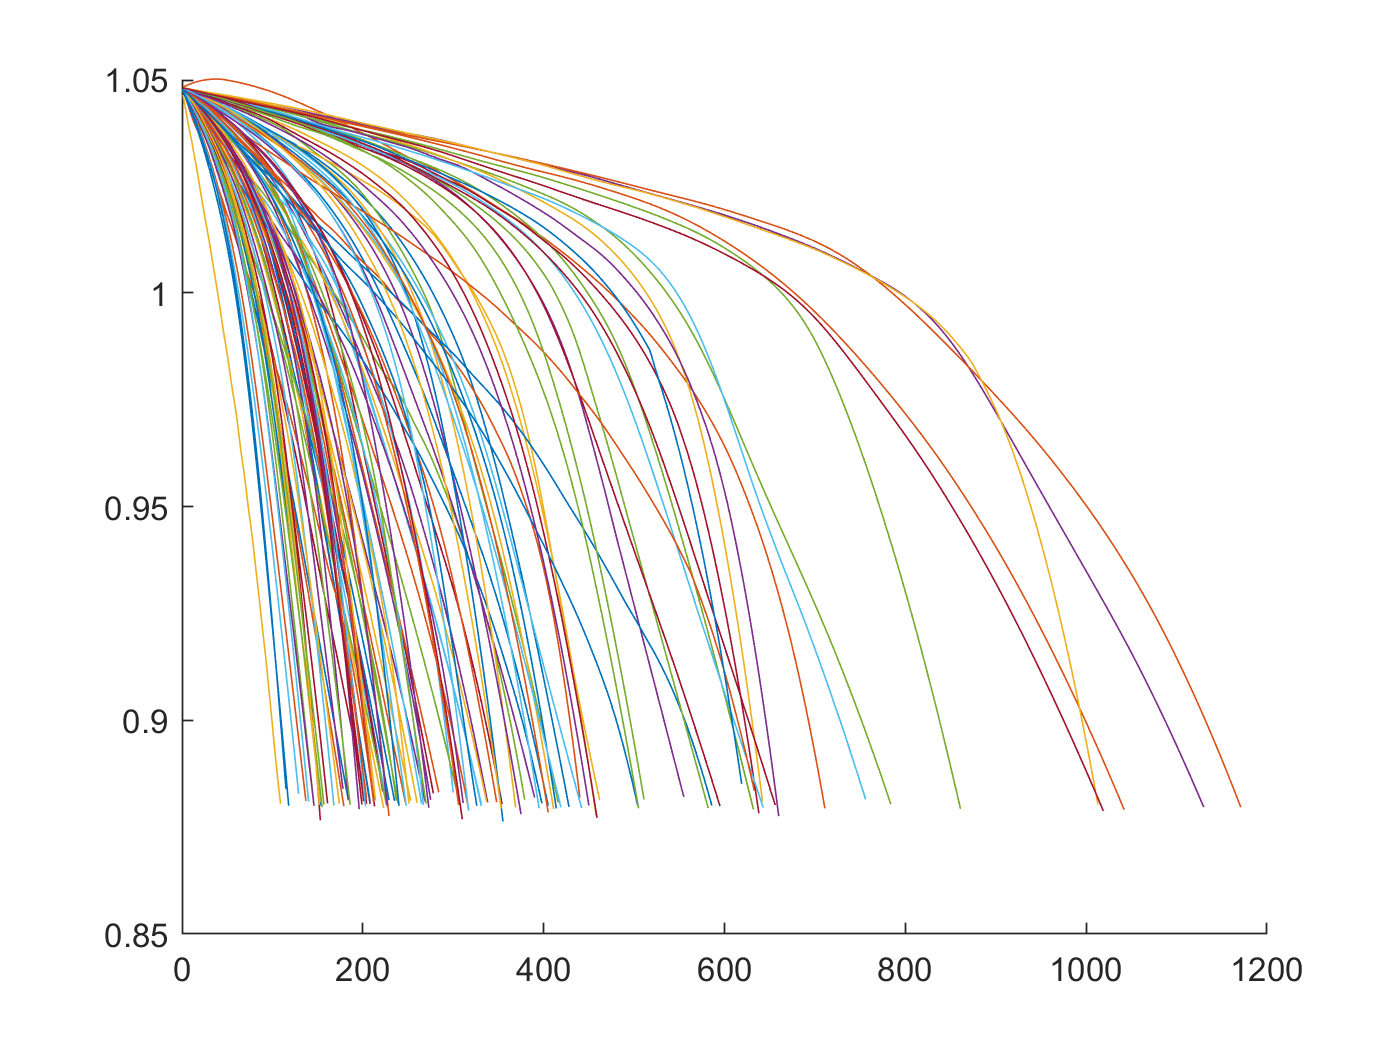

% here
figure
hold on
for i=1:length(idxAll)
    plot(battery_dataset(idxAll(i)).QDischargeSmooth)
end
hold off

batch 1

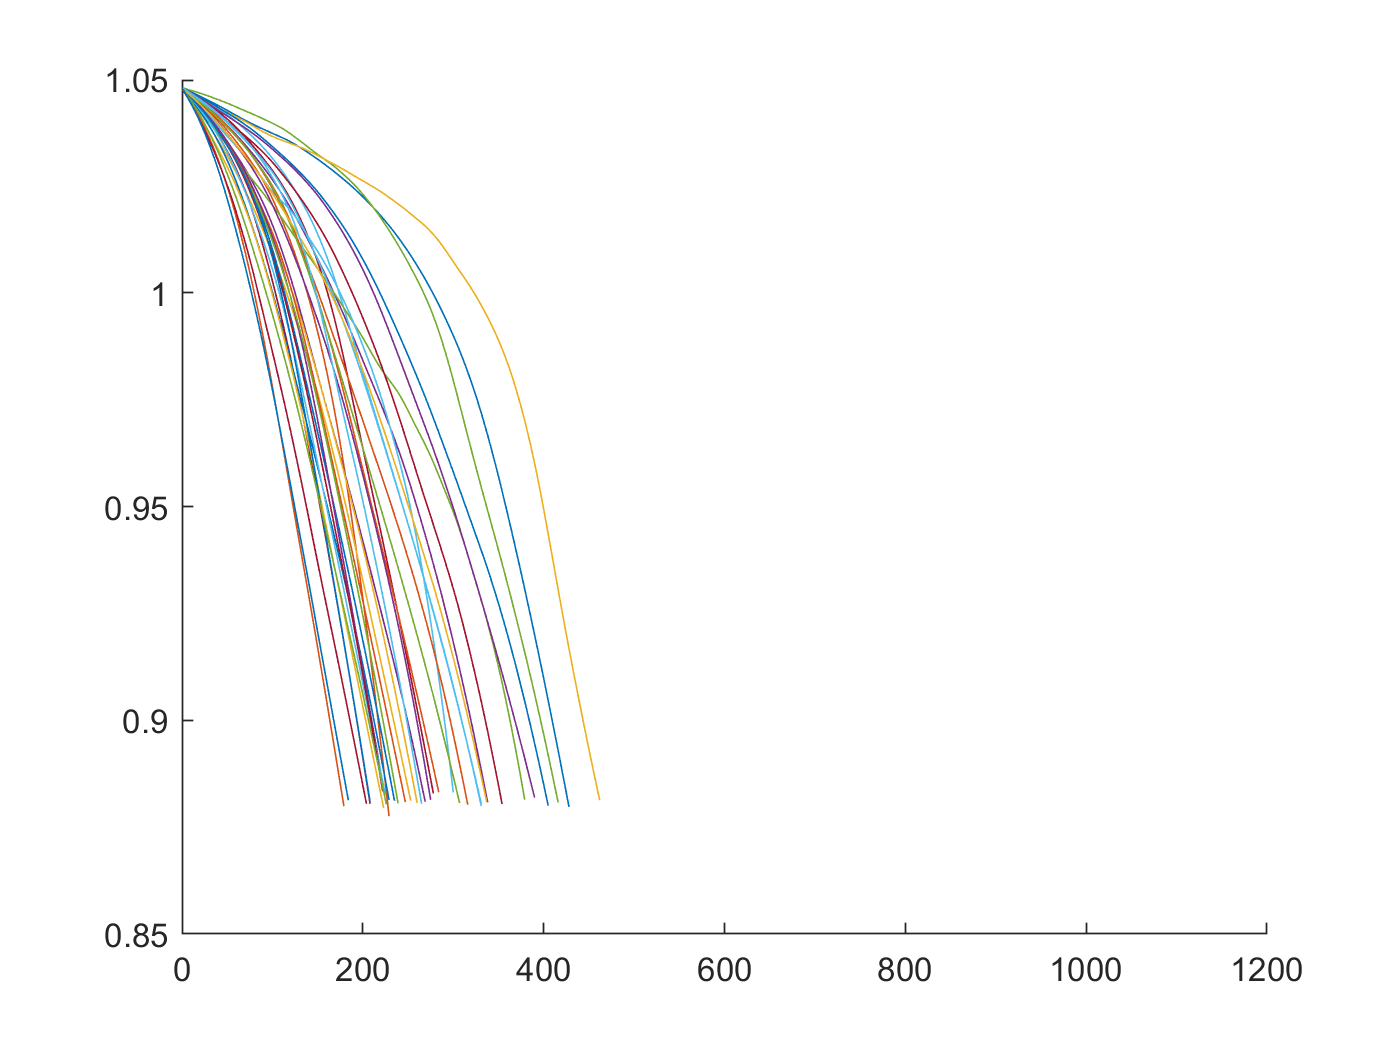

figure
hold on
for i=1:length(idx1)
    plot(battery_dataset(idx1(i)).QDischargeSmooth)
end
xlim ([0,1200])
hold off

batch 2

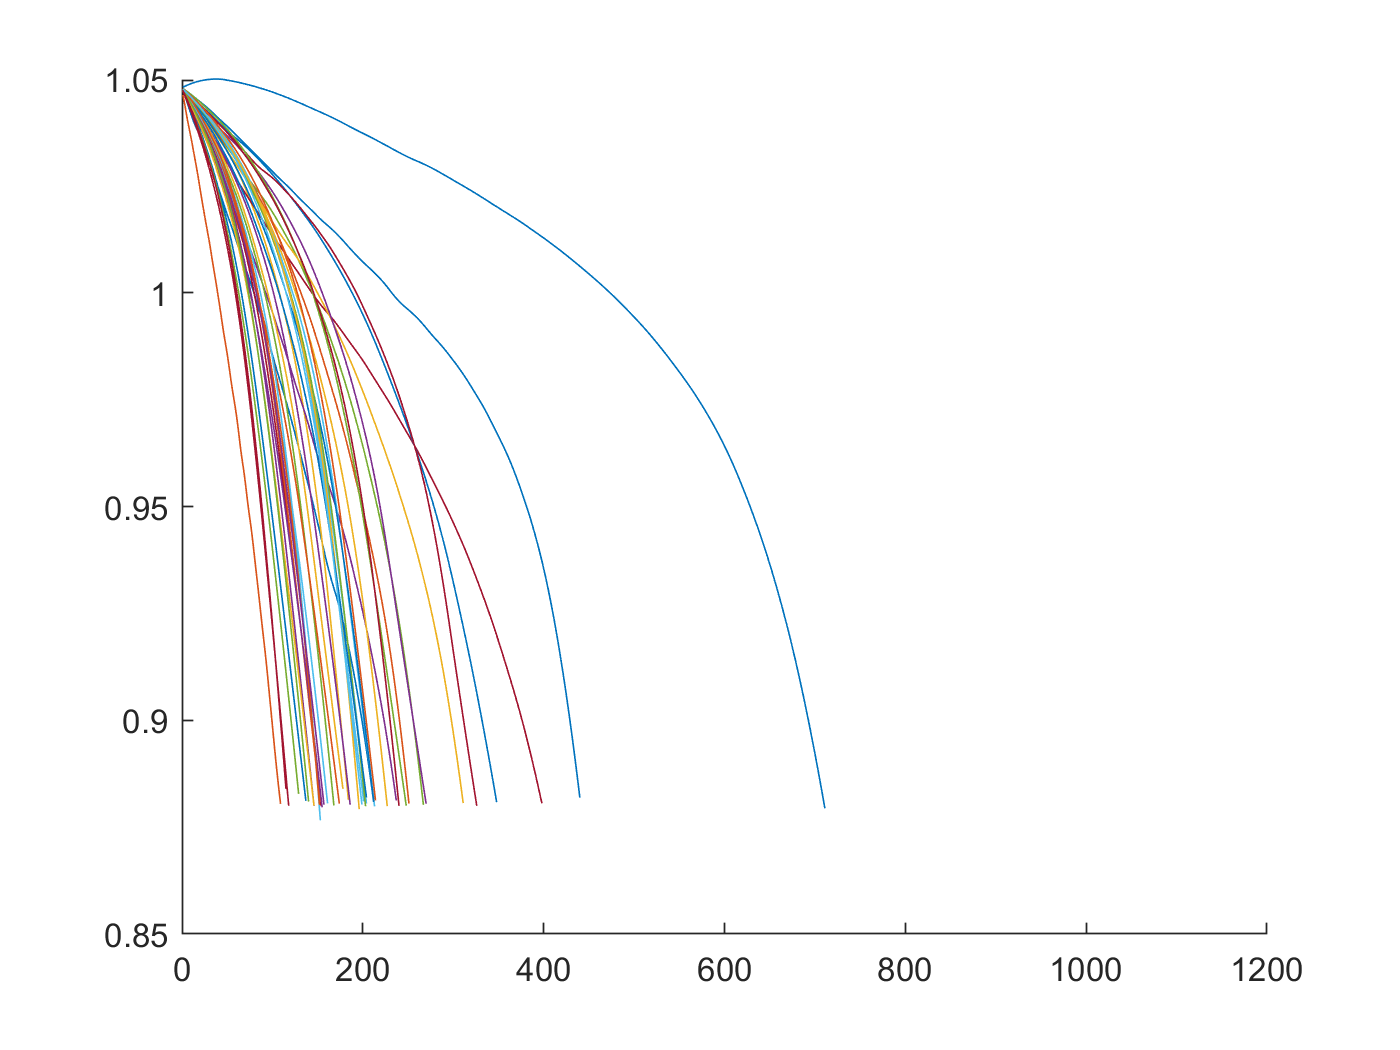

figure
hold on
for i=1:length(idx2)
    plot(battery_dataset(idx2(i)).QDischargeSmooth)
end
xlim ([0,1200])
hold off

batch 3

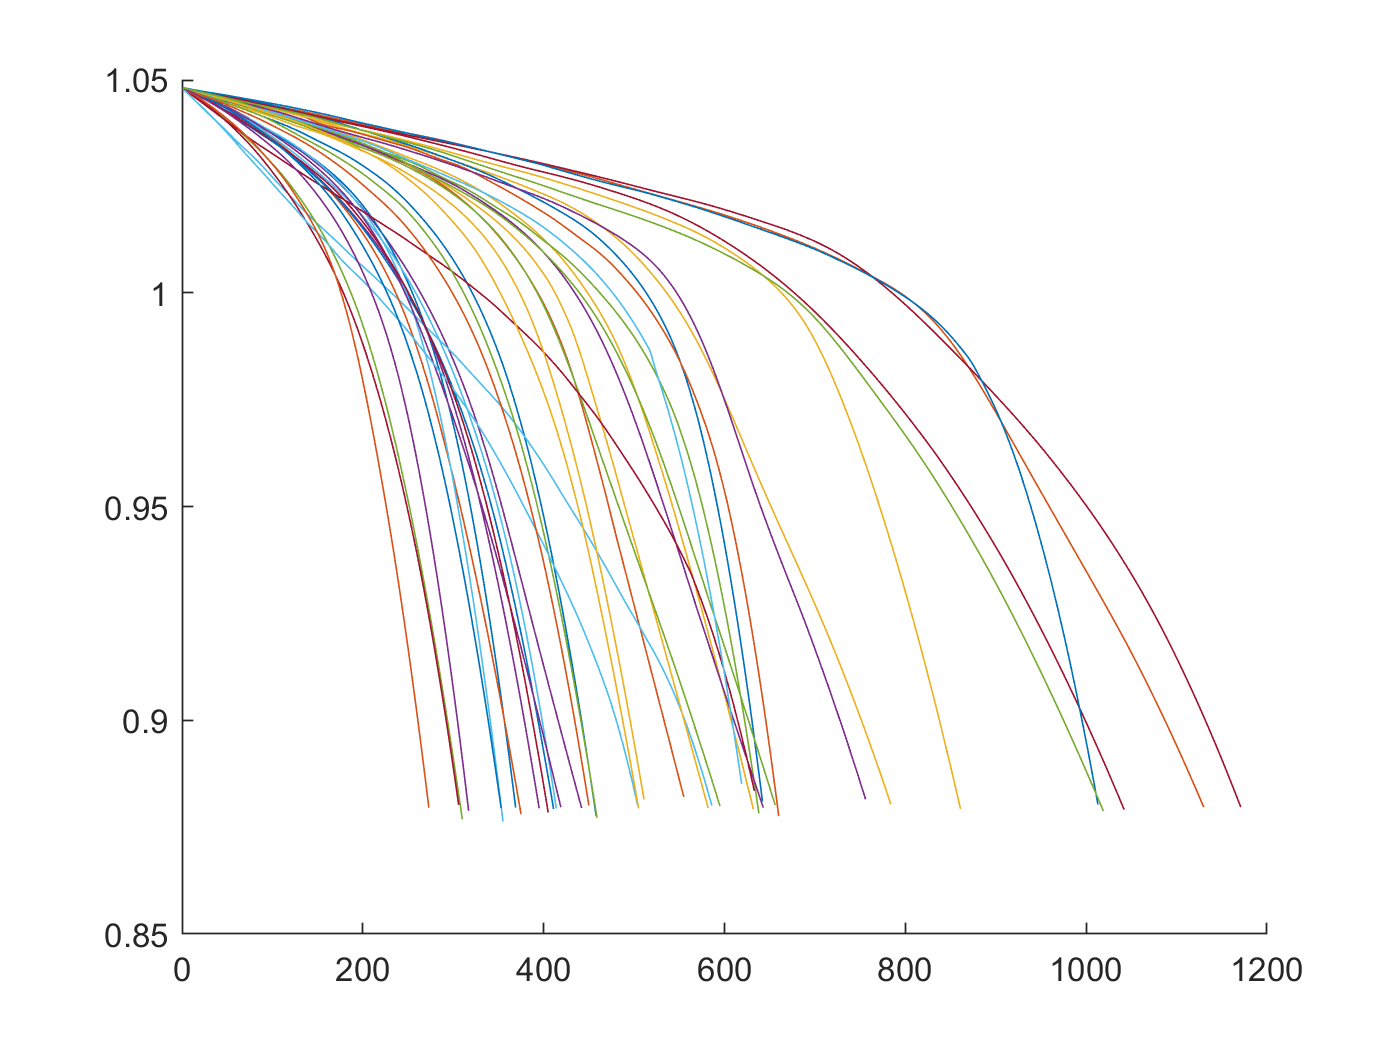

figure
hold on
for i=1:length(idx3)
    plot(battery_dataset(idx3(i)).QDischargeSmooth)
end
xlim ([0,1200])
hold off

#### train / valid / test - 위에서 batch 단위로 train / valid / test  를 분리하면 문제가 생길수 있다.

#### 따라서 균일하게 선정하자 

train

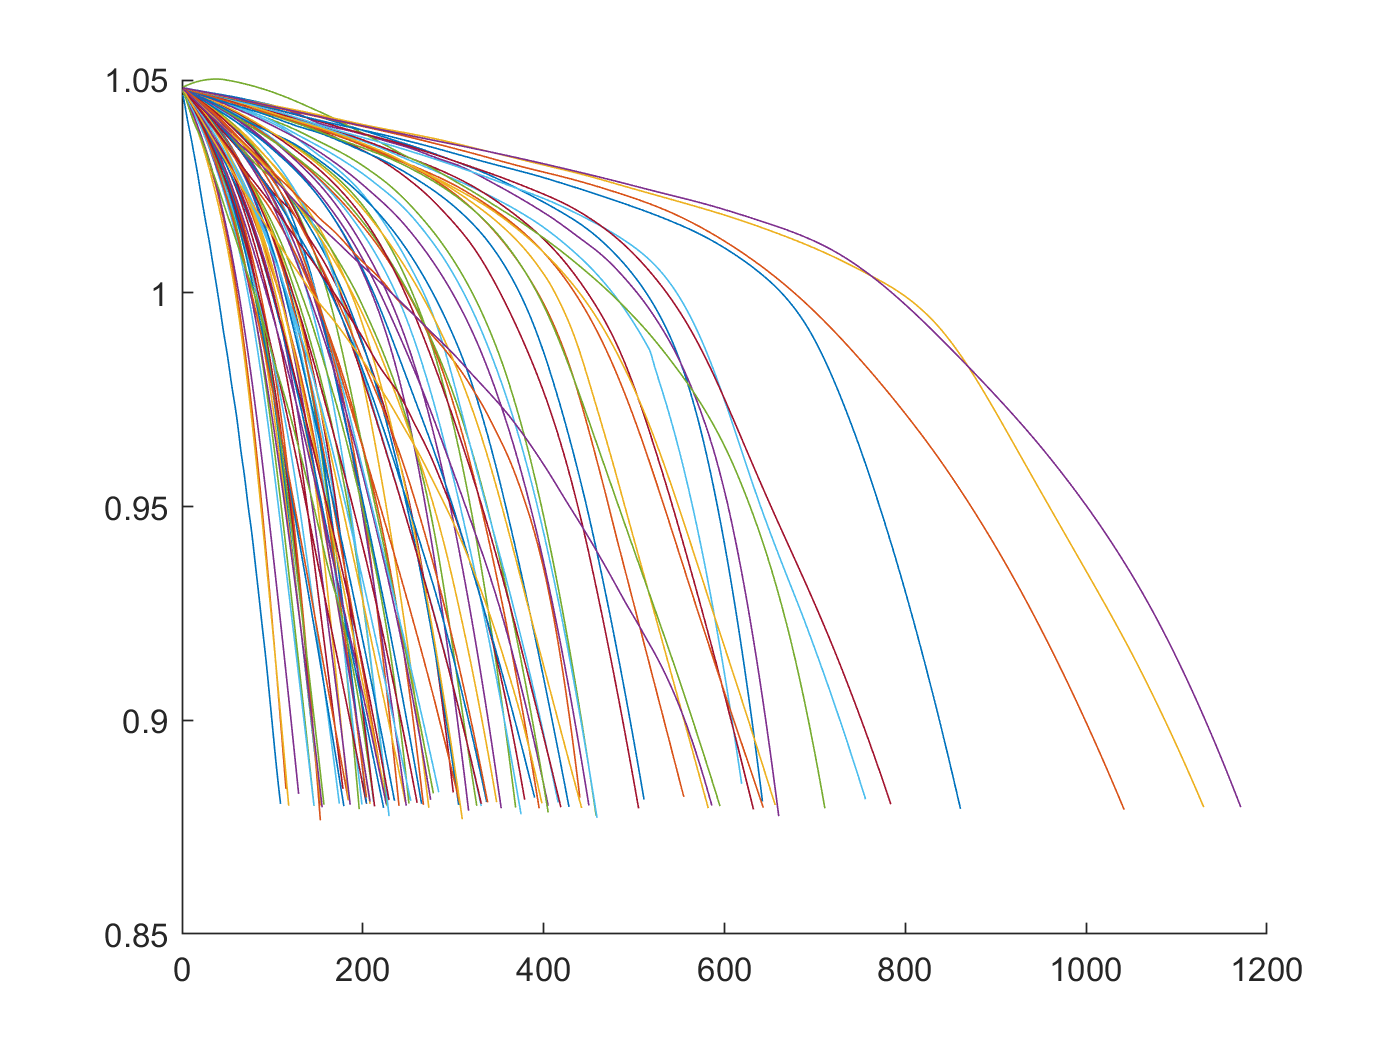

figure
hold on
for i=1:length(idxTrain)
    plot(battery_dataset(idxTrain(i)).QDischargeSmooth)
end
xlim ([0,1200])
hold off

valid

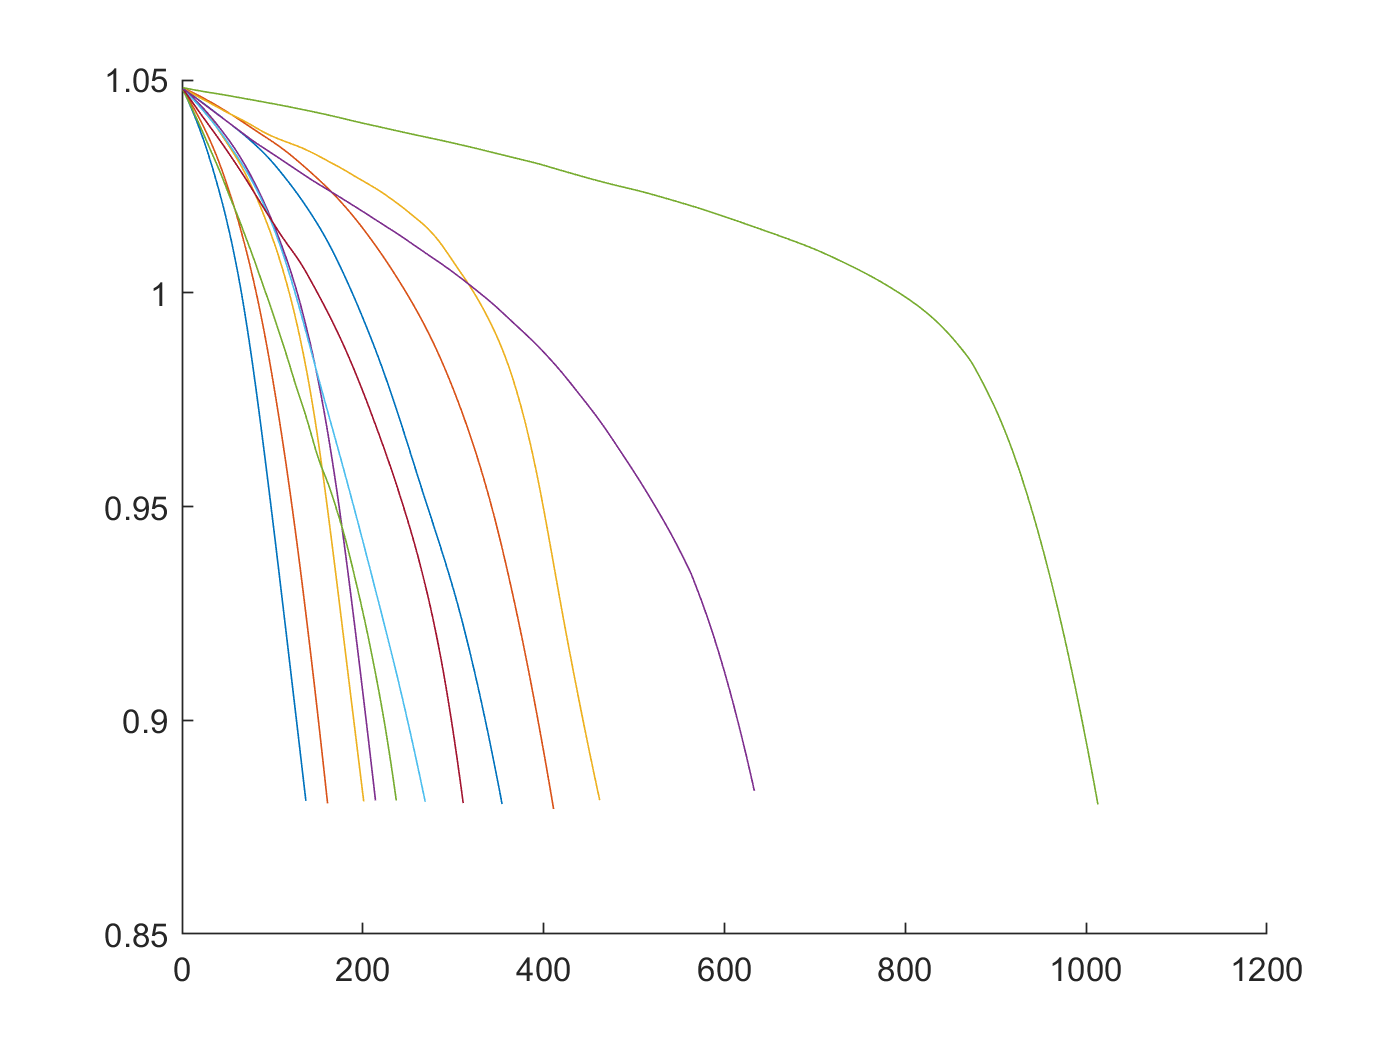

figure
hold on
for i=1:length(idxValid)
    plot(battery_dataset(idxValid(i)).QDischargeSmooth)
end
xlim ([0,1200])
hold off

test

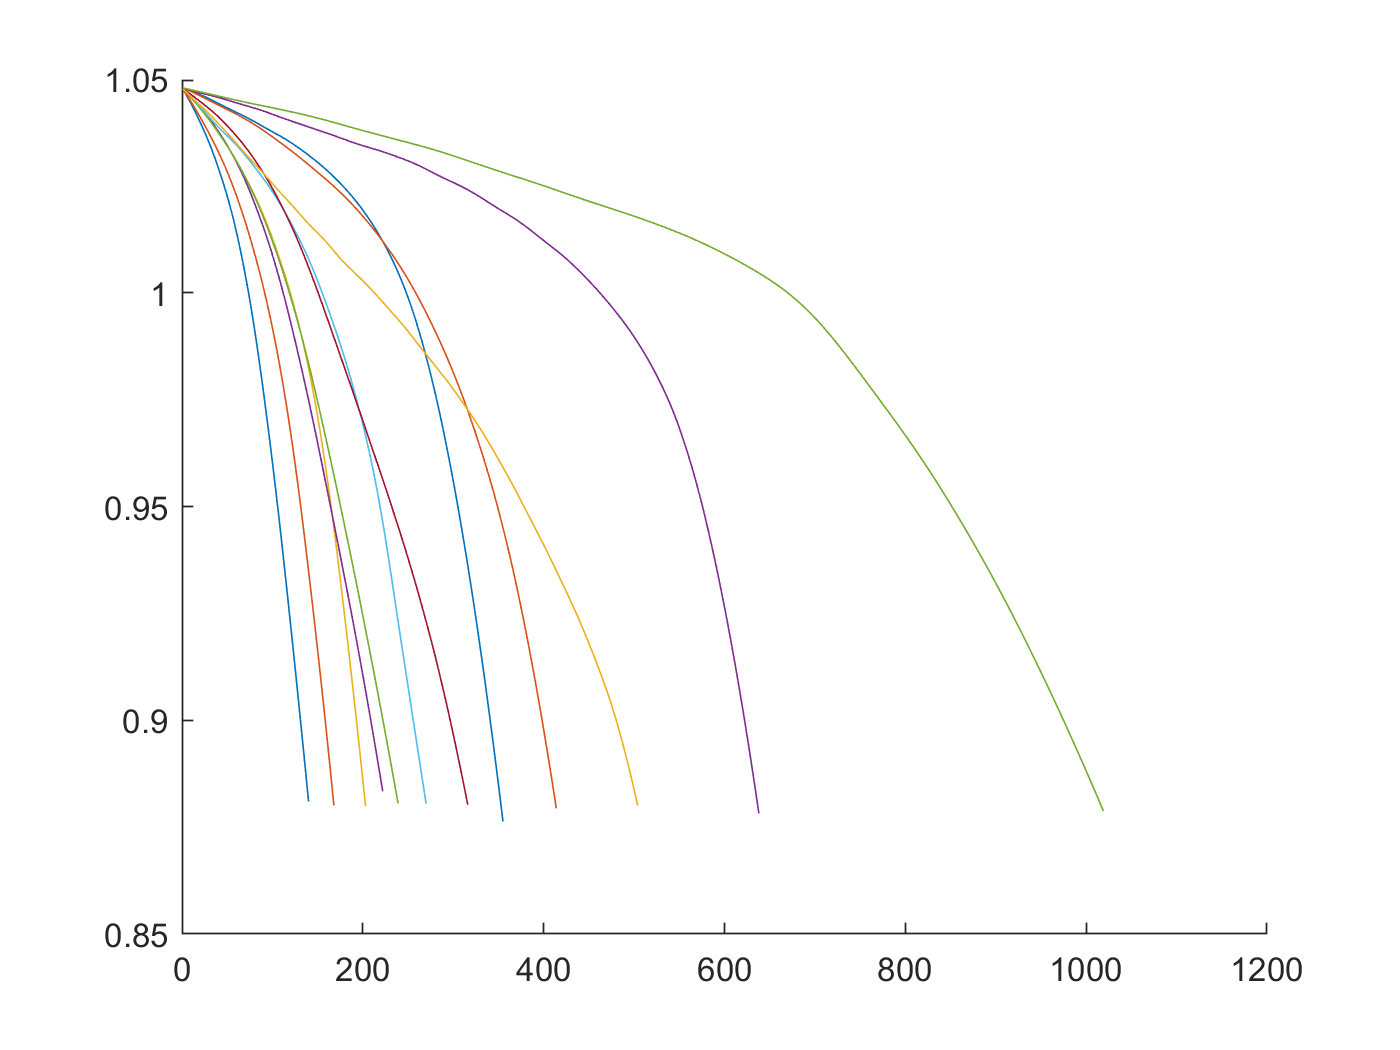

figure
hold on
for i=1:length(idxTest)
    plot(battery_dataset(idxTest(i)).QDischargeSmooth)
end
xlim ([0,1200])
hold off

#### 첫번째 cycle 의 충전 패턴으로 남은 cycle_life를 예측할 수 있을까?

#### 일단 한 배터리의 사이클별 충전전류를 확인해 보자.

#### 보면 패턴은 동일하지만 사이클이 증가함에 따라 SOH의 감소로 용량대비 점점 왼쪽으로 이동한다.

#### 그래프를 보면 Ic 에서 이상치가 보이나 일단 무시하자

% https://blogs.mathworks.com/pick/2011/02/11/create-multi-column-plot-legends/?from=kr
cycle_div = 50;
chargeCurrentIndex = linspace(0,1.2,100)

chargeCurrentIndex =          0    0.0121    0.0242    0.0364    0.0485    0.0606    0.0727    0.0848    0.0970    0.1091    0.1212    0.1333    0.1455    0.1576    0.1697    0.1818    0.1939    0.2061    0.2182    0.2303    0.2424    0.2545    0.2667    0.2788    0.2909    0.3030    0.3152    0.3273    0.3394    0.3515    0.3636    0.3758    0.3879    0.4000    0.4121    0.4242    0.4364    0.4485    0.4606    0.4727    0.4848    0.4970    0.5091    0.5212    0.5333    0.5455    0.5576    0.5697    0.5818    0.5939


battery_dataset(1).Ic

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002   

size(battery_dataset(1).Ic)

ans =    428   100


length(battery_dataset(1).Ic)

ans = 428

battery_dataset(1).Ic(1,:)

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999


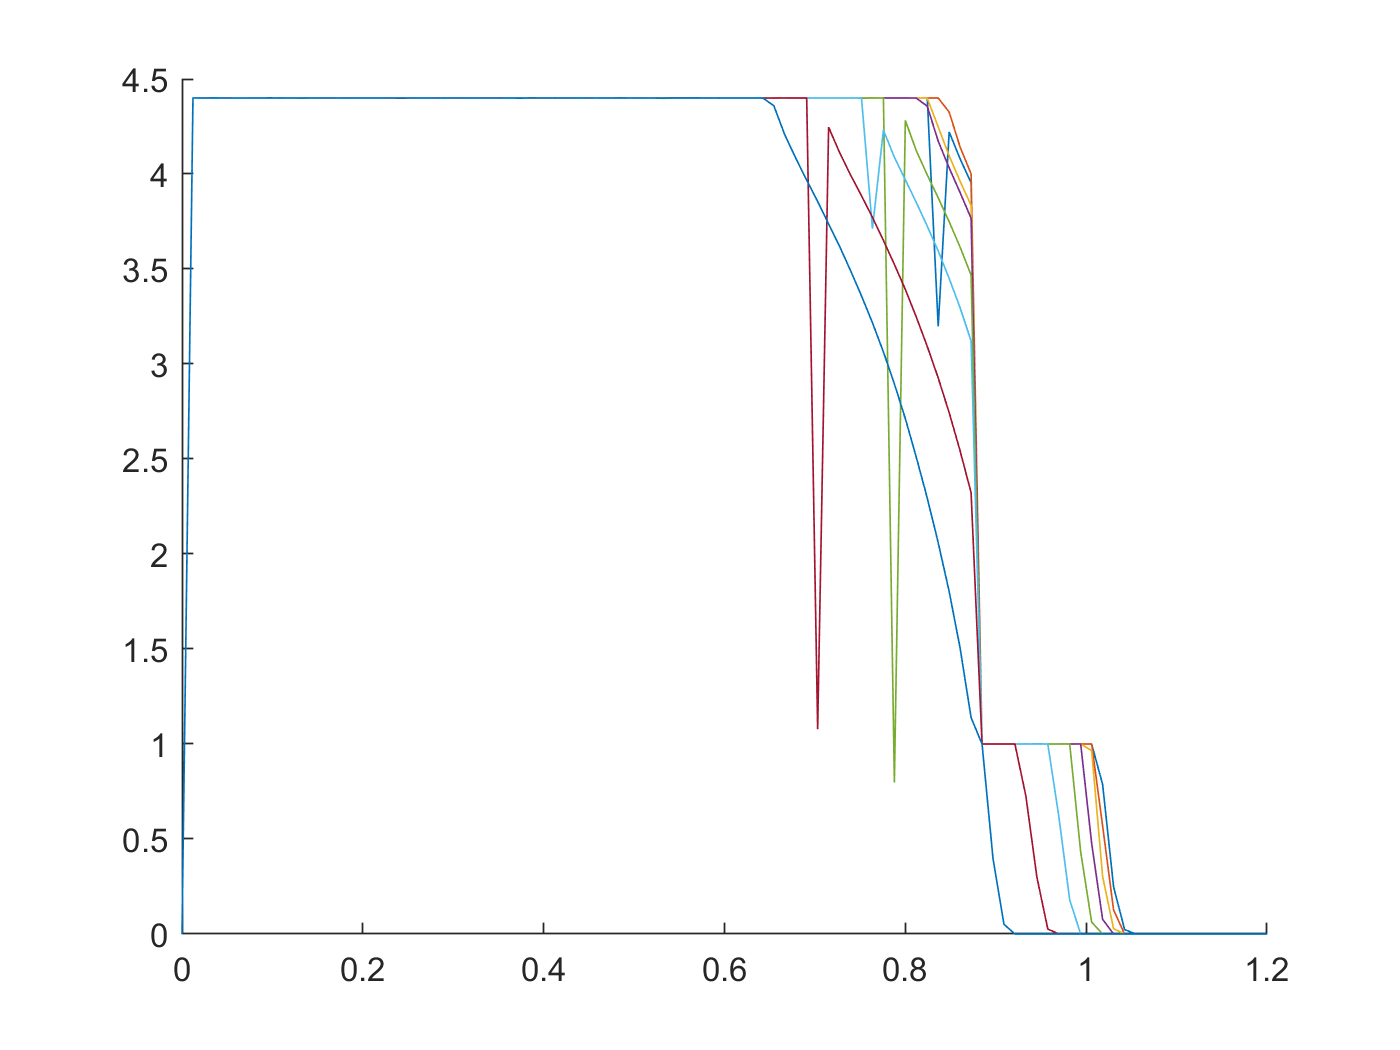

figure, hold on
for i = 1 : length(battery_dataset(1).Ic)
    if rem(i,cycle_div) == 0
    plot(chargeCurrentIndex,battery_dataset(1).Ic(i,:))
    end 
end
hold off

#### 그럼 각 배터리의 첫번째 Cycle의 충전전류와 남은 사이클의 관계를 확인해 보자

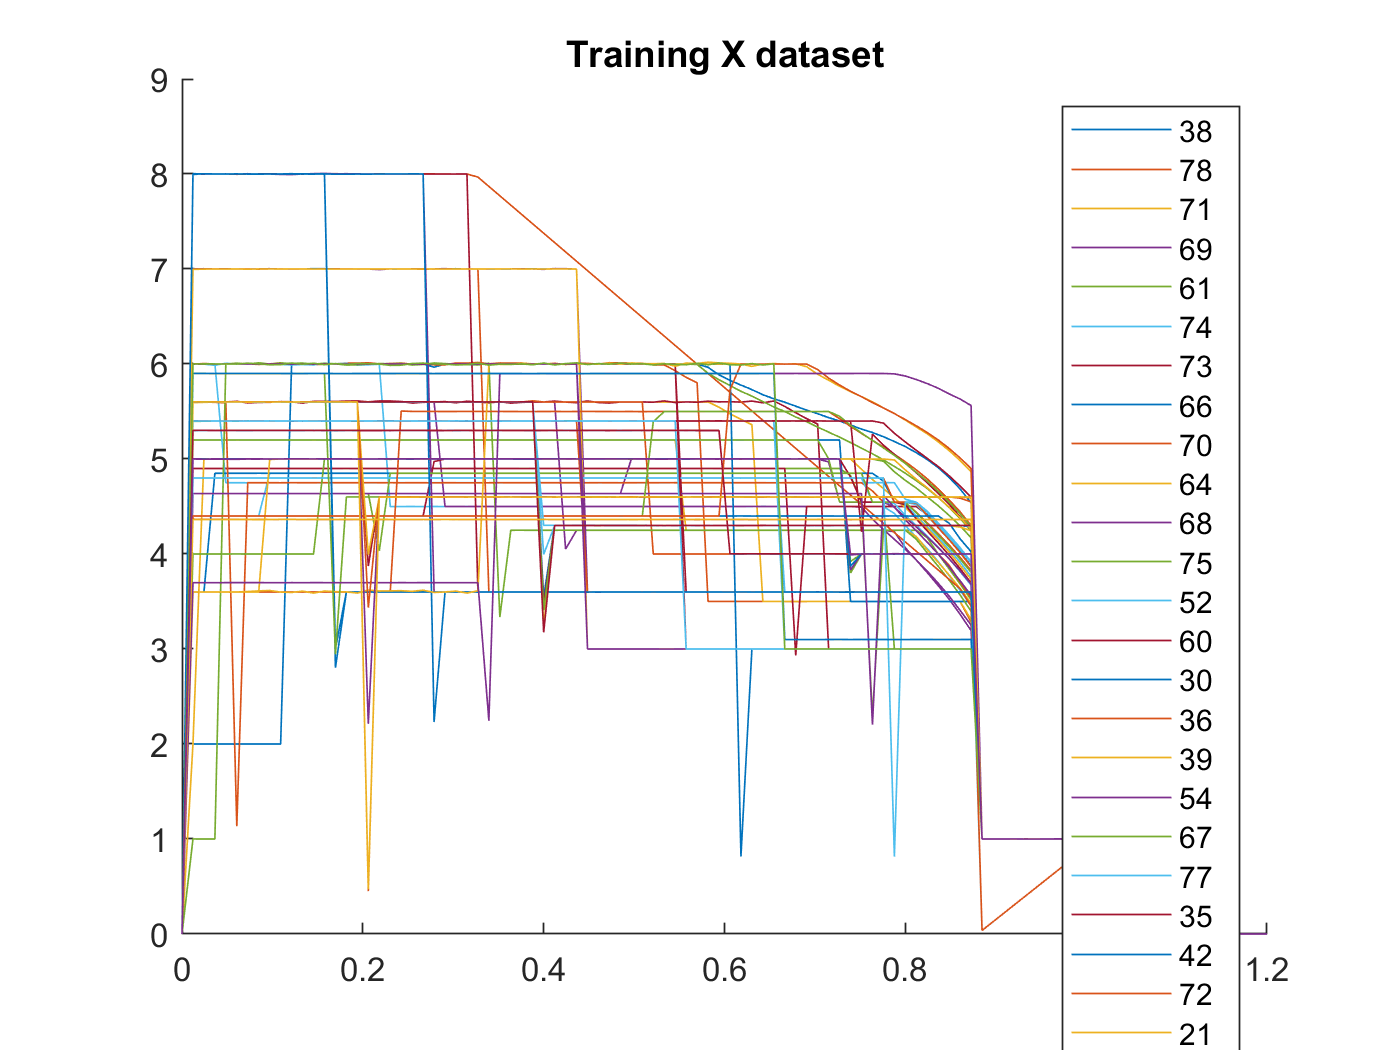

nLines = length(idxTrain);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(chargeCurrentIndex,battery_dataset(i).Ic(1,:))
    legend_str{j} = num2str(i);
end
hold off
title 'Training X dataset'
legend(legend_str)%,'location','NorthWest')

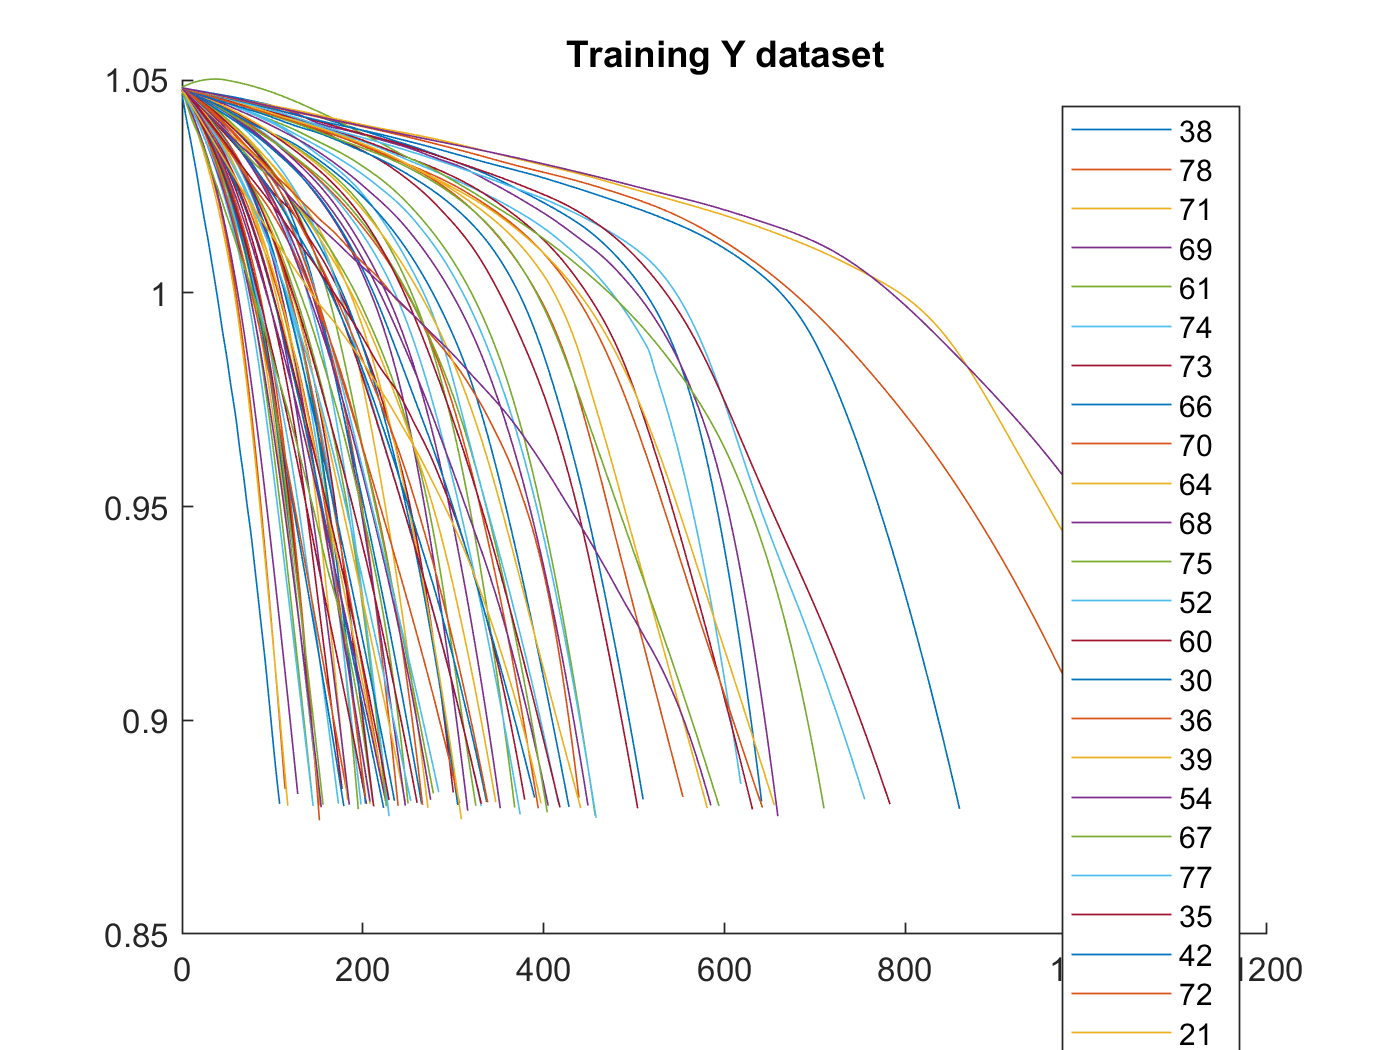



legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTrain)
    i = idxTrain(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Training Y dataset'
legend(legend_str) %,'location','NorthWest')

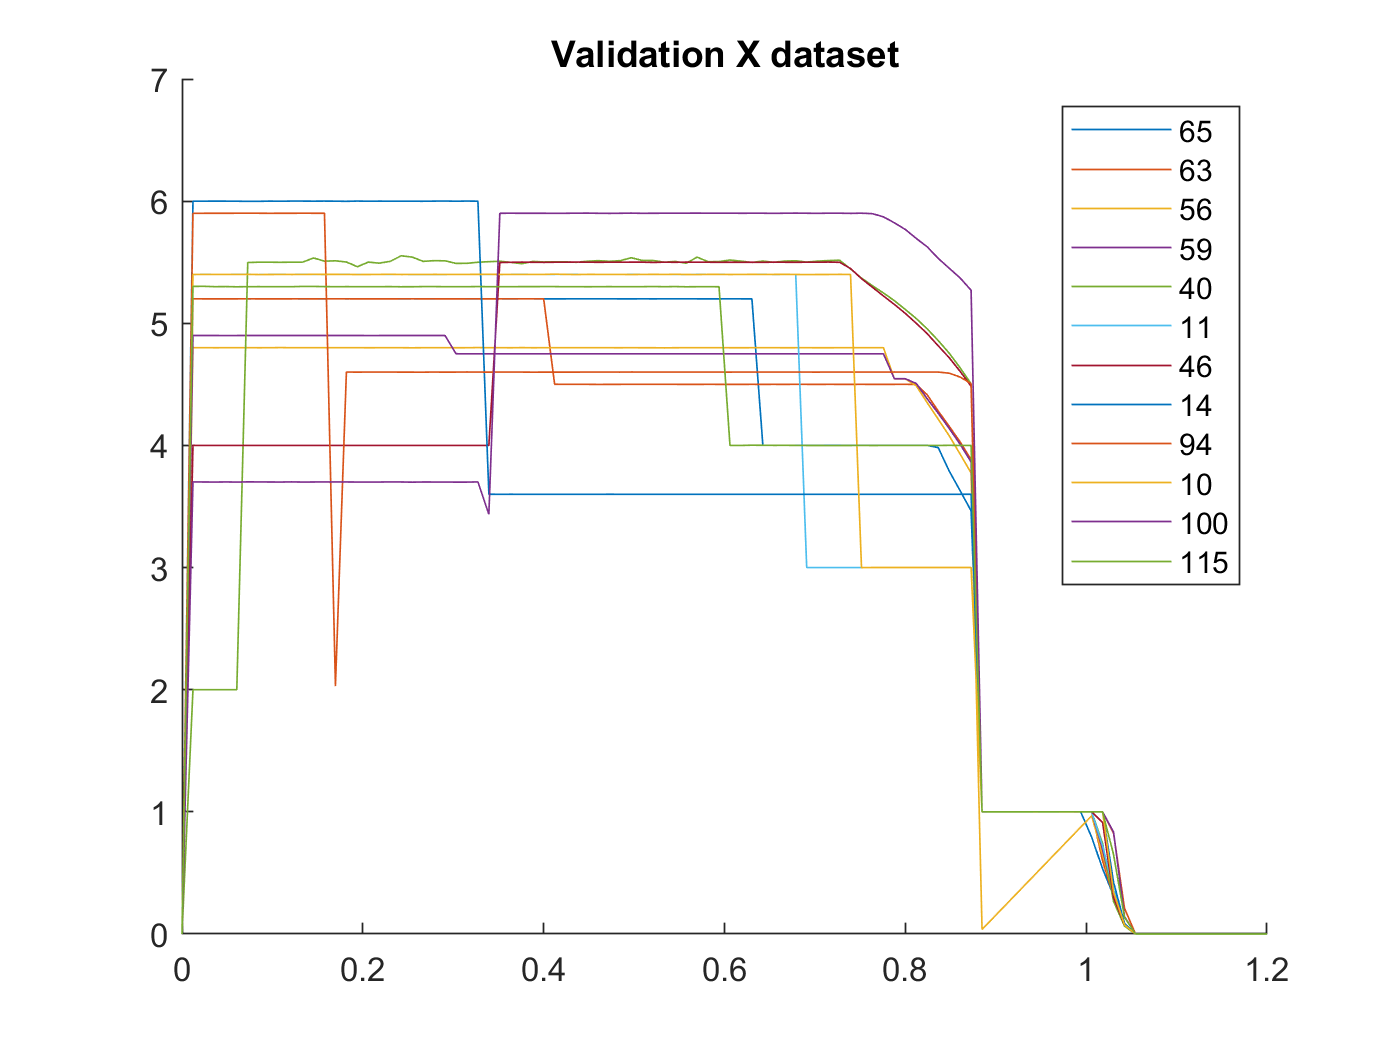



nLines = length(idxValid);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(chargeCurrentIndex,battery_dataset(i).Ic(1,:))
    legend_str{j} = num2str(i);
end
hold off
title 'Validation X dataset'
legend(legend_str)

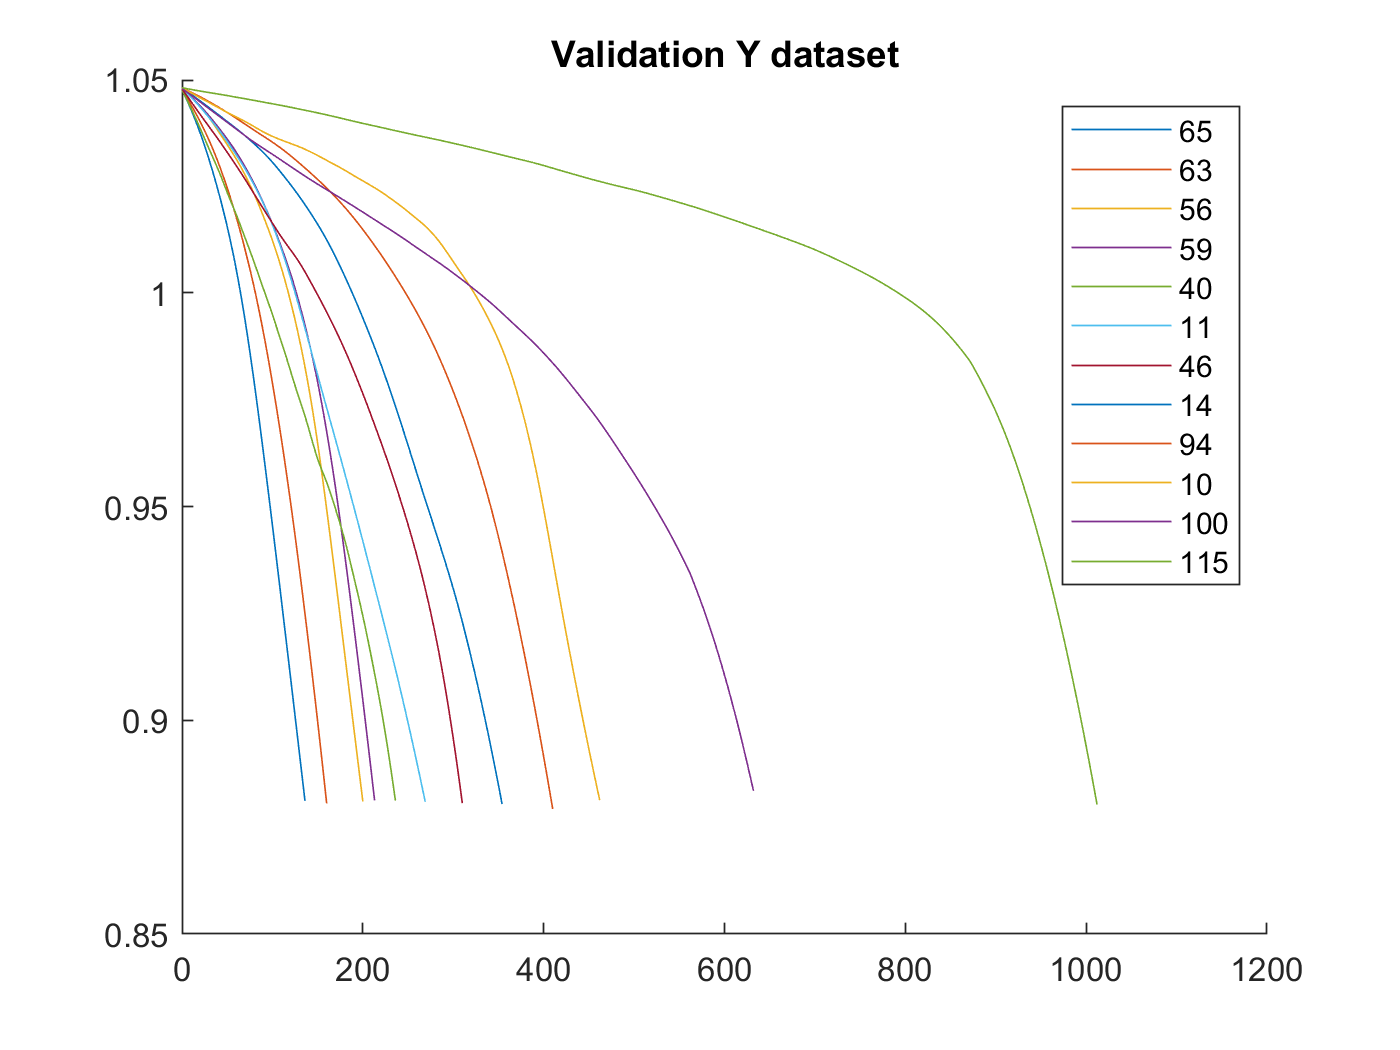


legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxValid)
    i = idxValid(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Validation Y dataset'
legend(legend_str)

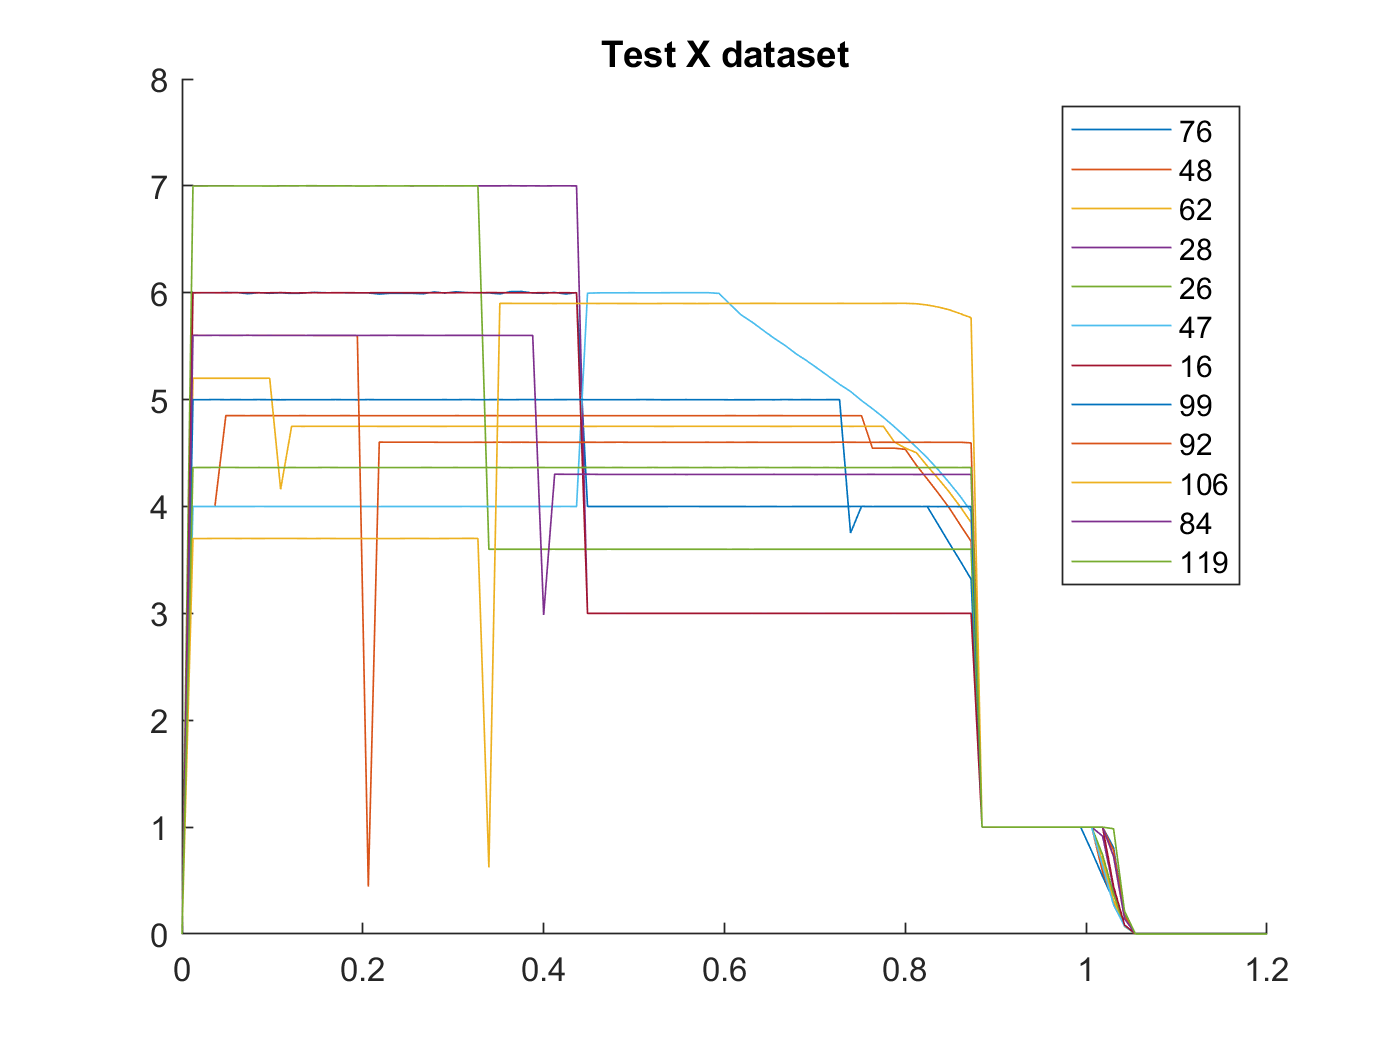


nLines = length(idxTest);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(chargeCurrentIndex,battery_dataset(i).Ic(1,:))
    legend_str{j} = num2str(i);
end
hold off
title 'Test X dataset'
legend(legend_str)

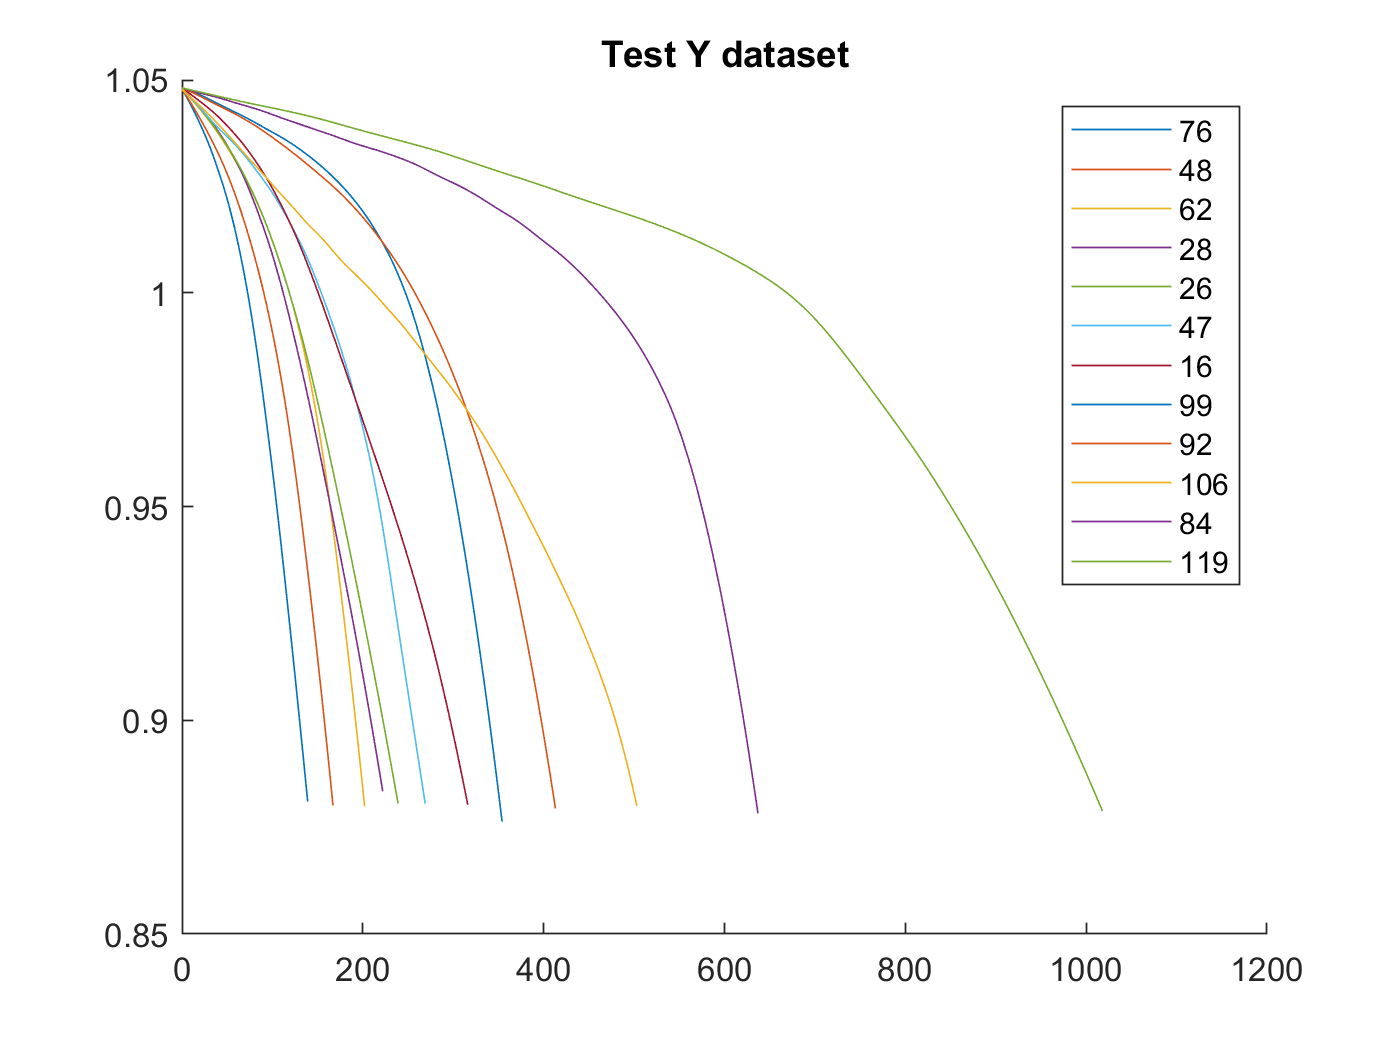


figure
hold on 
for j = 1 : length(idxTest)
    i = idxTest(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)